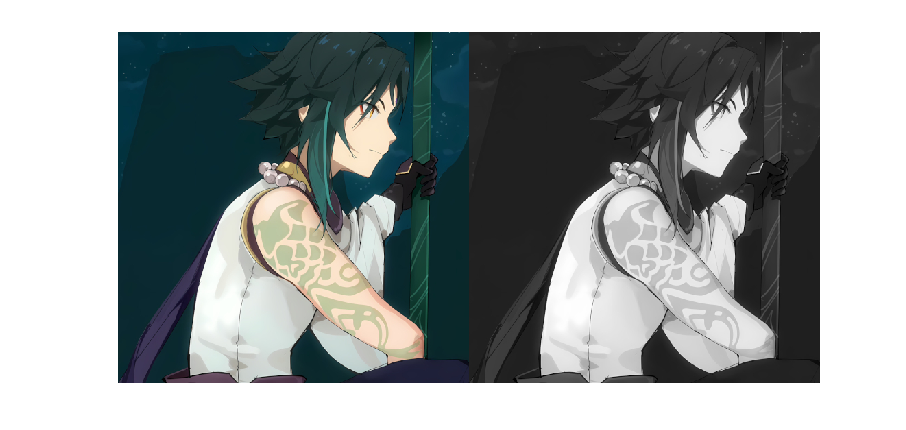

im = imread("xiao.jpeg");
img = rgb2gray(im);
imshowpair(im, img, "montage");

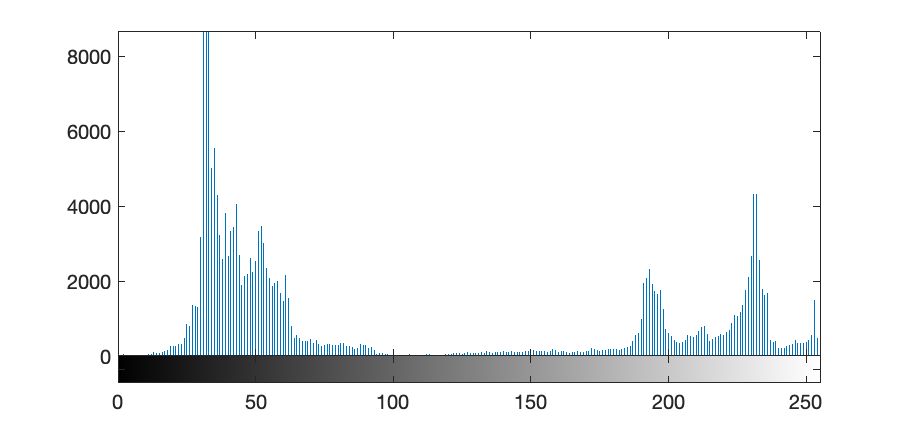

imhist(img);

1.图像二值化(阈值t)。

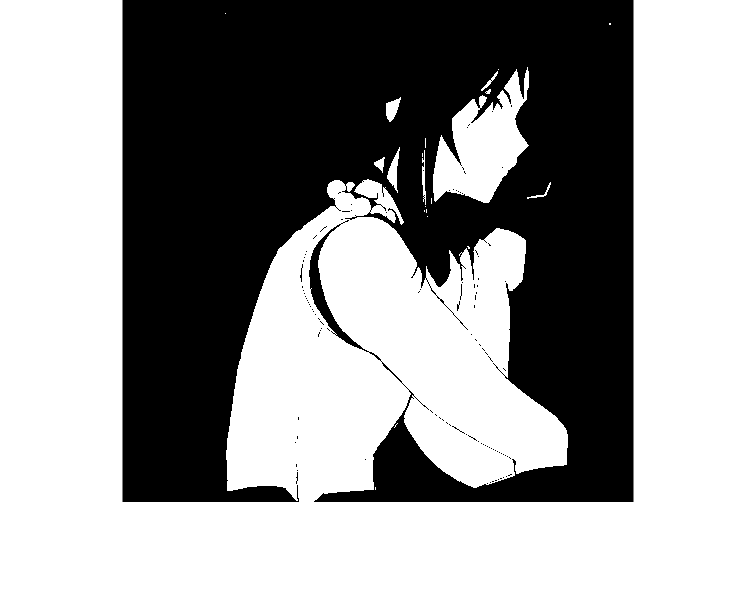

t =128;
imb = 0 * (img < t) + 1 * (img >= t);
imshow(imb);

2.实现简单直方图阈值分割或otsu图像分割算法，输出分割阈值。

3.对一张图片（文本图片或其他具有双峰直方图性质的图片）进行图像分割，用所写算法进行分割，分析处理结果（阈值是否合适，图像中哪些地方分割的不好，可能原因是什么)。

his = tabulate(img(:));

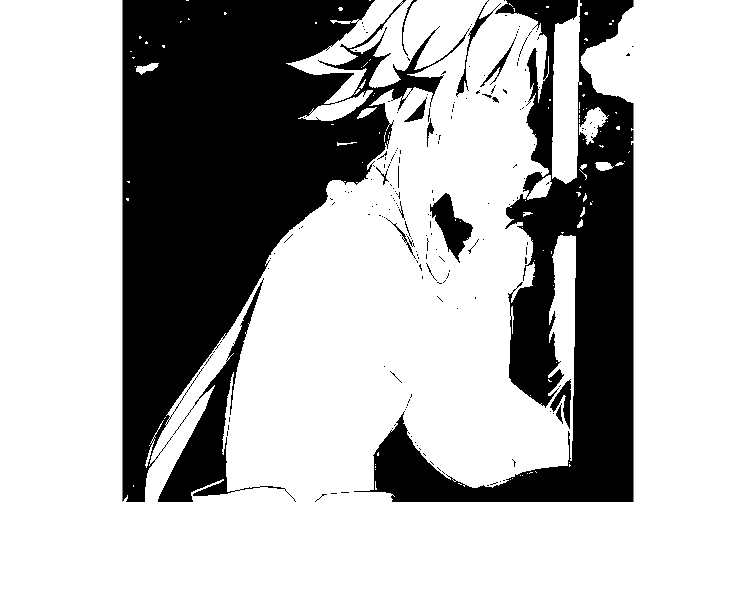

T = 0;
n = 1;
while T <= 50
    T = T + his(n, 3);
    n = n + 1;
end
imb = 0 * (img < n) + 1 * (img >= n);
imwrite(imb, 'sb.jpg')
imshow(imb);

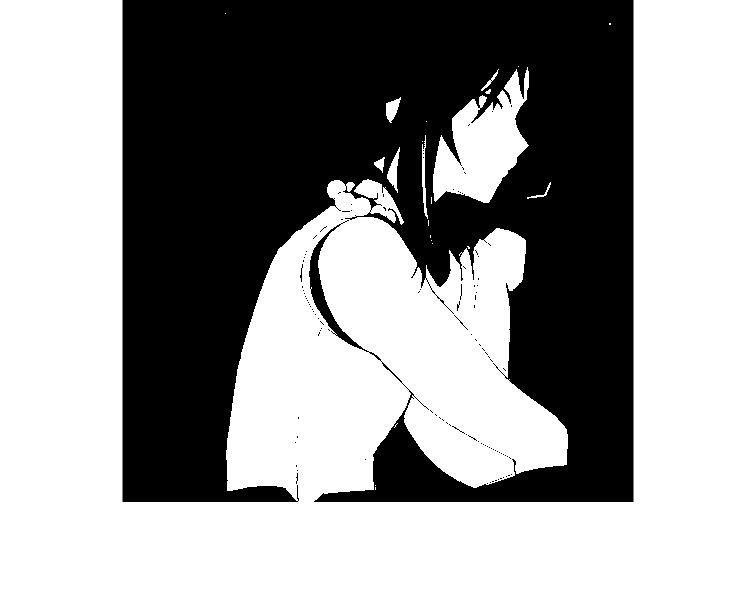

k = otsu(his);
imb = 0 * (img < k) + 1 * (img >= k);
imshow(imb);

function k = otsu(his)
    miu = sum(his(:, 1).*(his(:, 3)/100));
    sigm = 0;
    km = 0;
    for k = 0 : 254
        miuk = sum(his(1: k + 1, 1).*(his(1: k + 1, 3) / 100));
        omega = sum(his(1: k + 1, 3) / 100);
        sigma = (miu * omega - miuk)^2 / (omega * (1 - omega));
        if sigm < sigma
            sigm = sigma;
            km = k;
        end
    end
    k = km;
end